## Cue only ! dummy coding

## Pain  cue

#### Pain :: load dataset

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/multivariate_24dofcsd/s03_concatnifti';
con_list = dir(fullfile(mount_dir, '*/*_task-social_run-pain_ev-cue_l2norm.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii


sampleto = '/Volumes/spacetop_projects_social/analysis/fmri/spm/multivariate_24dofcsd/s03_concatnifti/sub-0005/sub-0005_task-social_run-pain_ev-cue_l2norm.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 1116177660 bytes
Loading image number:  2795
Elapsed time is 147.845683 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
.fullpath should have image name for each image column in .dat
Attempting to expand image filenames in case image list is unexpanded 4-D images
Number of unique values in dataset: 96624734  Bit rate: 26.53 bits


#### Pain :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

SPM12: spm_check_registration (v7759)              17:16:19 - 04/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


#### Pain :: Plot diagnostics, remove outliers

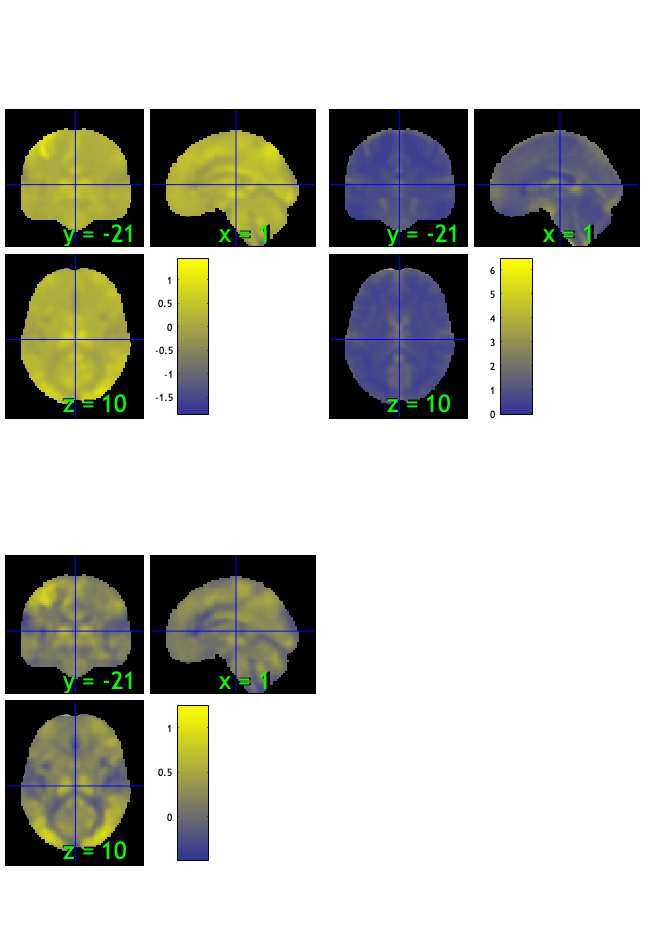

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 52.92%
Expected 139.75 outside 95% ellipsoid, found  73

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 73 images		Cases 43 48 69 73 76 78 83 84 96 106 107 108 165 191 294 331 391 401 463 466 494 559 592 1015 1041 1127 1165 1166 1174 1227 1353 1410 1474 1568 1585 1640 1645 1700 1742 1751 1905 1907 1922 1926 1962 2012 2019 2024 2027 2073 2079 2121 2126 2142 2145 2162 2182 2202 2256 2280 2288 2299 2320 2328 2378 2393 2547 2548 2675 2754 2760 2775 2785 

Retained 7 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 52.70%
Expected 139.75 outside 95% ellipsoid, found  86

SPM12: spm_check_registration (v7759)              17:22:44 - 04/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

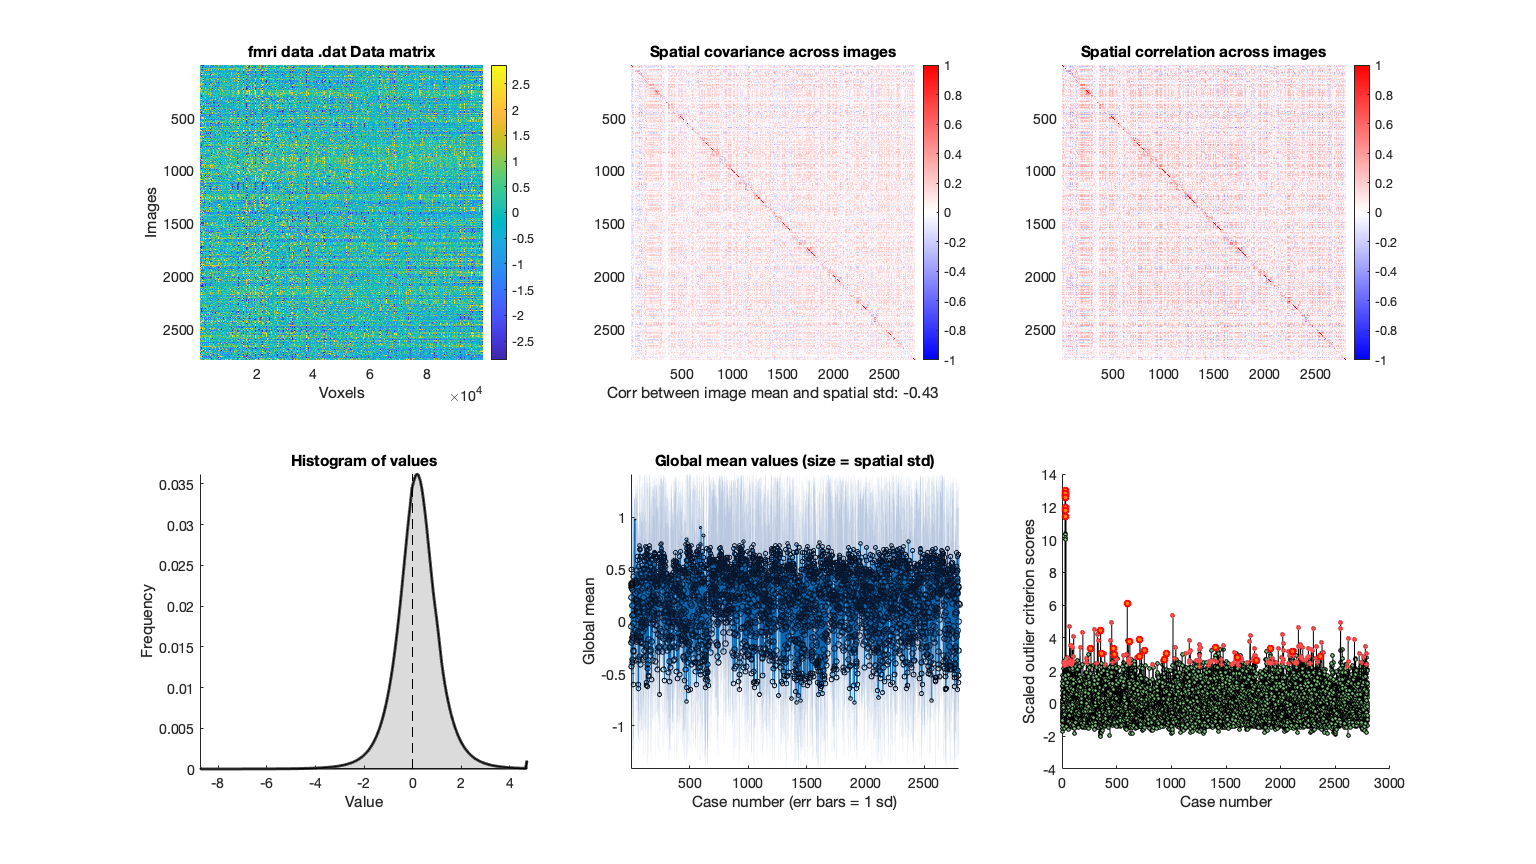

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


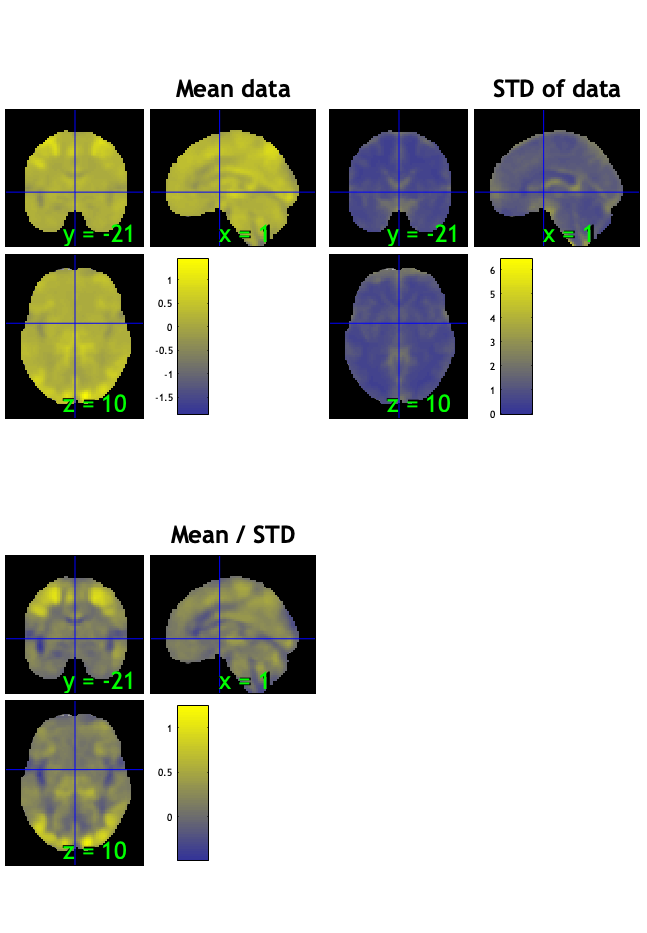

wh_outlier_uncorr = 2795×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


wh_outlier_corr = 2795×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Pain :: run robfit

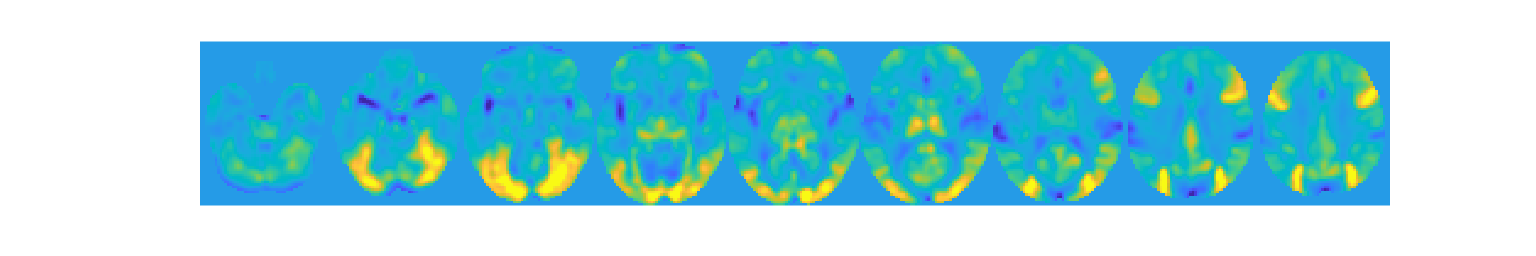

set(gcf,'Visible','on')

figure ('Visible', 'on');
drawnow, snapnow;

#### Pain :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))

current length is 2795


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.fullpath(~wh_outlier_corr,:)

The logical indices in position 1 contain a true value outside of the array bounds.

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

#### Pain :: ttest

t = ttest(con);
orthviews(t)
drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');
orthviews(fdr_t)
drawnow, snapnow;

create_figure('montage'); axis off
montage(fdr_t)
drawnow, snapnow;

## Vicarious  cue

clear all

#### Vicarious  :: load dataset

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/multivariate_24dofcsd/s03_concatnifti';
con_list = dir(fullfile(mount_dir, '*/*_task-social_run-vicarious_ev-cue_l2norm.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
full = fmri_data()
for f = 1:size(con_files,1)
    con_data_obj = fmri_data(con_files(f));
    m = mean(con_data_obj);
    m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
    full = create(full, 'dat', m.dat, 'image_names', m.image_names, 'fullpath', m.fullpath )
    
end


#### Vicarious :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

#### Vicarious :: Plot diagnostics, remove outliers

drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Vicarious :: run robfit

set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;

#### Vicarious :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))
%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

#### Vicarious :: ttest

t = ttest(con);
orthviews(t)
drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');
orthviews(fdr_t)
drawnow, snapnow;

create_figure('montage'); axis off
montage(fdr_t)
drawnow, snapnow;

## Cognitive cue

#### Cognitive :: load dataset

#### Cognitive :: load dataset

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/multivariate_24dofcsd/s03_concatnifti';
con_list = dir(fullfile(mount_dir, '*/*_task-social_run-cognitive_ev-cue_l2norm.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

#### Cognitive :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

#### Cognitive :: Plot diagnostics, remove outliers

drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Cognitive :: run robfit

set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;

#### Cognitive :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))
%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

#### Cognitive :: ttest

t = ttest(con);
orthviews(t)
drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');
orthviews(fdr_t)
drawnow, snapnow;

create_figure('montage'); axis off
montage(fdr_t)
drawnow, snapnow;

#### General :: load dataset

#### General :: load dataset

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/multivariate_24dofcsd/s03_concatnifti';
con_list = dir(fullfile(mount_dir, '*/*_task-social_run-general_ev-cue_l2norm.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

#### General :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

#### General :: Plot diagnostics, remove outliers

drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### General :: run robfit

set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;

#### General :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))
%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

#### General :: ttest

t = ttest(con);
orthviews(t)
drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');
orthviews(fdr_t)
drawnow, snapnow;

create_figure('montage'); axis off
montage(fdr_t)
drawnow, snapnow;